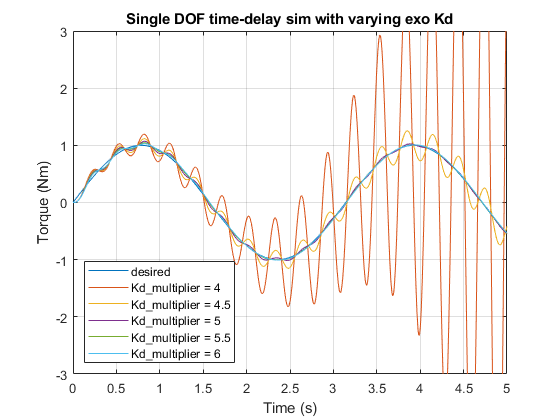

close all; clear all;
global Kd

lags = [0.1];
tspan = [0 5];

n_points = 5;

kd = linspace(4,6,n_points);

legendcell{1} = "desired";

for i = 1:n_points
    Kd = 1.25*kd(i);
    sol = dde23(@ddefun, lags, @history, tspan);
%     rmss(i) = rms(sin(2*sol.x)-sol.y(1,:));
    if i == 1
        plot(sol.x,sin(2*sol.x)); hold on;
    end
    plot(sol.x,sol.y(1,:)); 
    legendcell{i+1} = "Kd\_multiplier = " + num2str(kd(i));
    grid on
end


% plot(sol.x,sin(2*sol.x))
% plot(sol.x,sol.y(3,:)); 
xlabel('Time (s)');
ylabel('Torque (Nm)');
legend(legendcell,'Location','SouthWest')
title('Single DOF time-delay sim with varying exo Kd')
ylim([-3 3])


% figure()
% plot(kd,rmss)